L(s) = 5/(s+1)^3

s = tf('s'); 
L = 5/(s+1)^3

L =
 
            5
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.
Model Properties


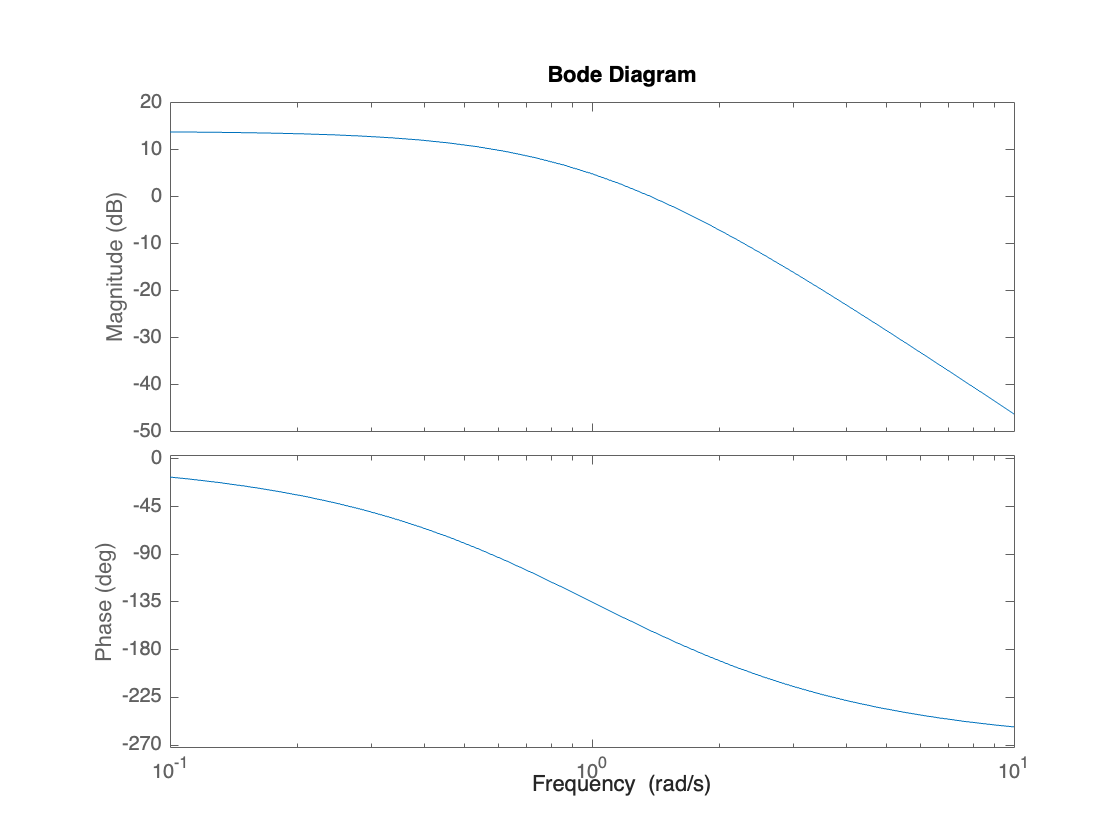

figure;
bode(L)

Margem de ganho:

- frequencia na qual defasagem é de 180 graus: 1.75 rad/s (freq. de cruzamento de fase)

- Nessa frequência, amplitude é -4.4 dB (logo: Margem de ganho é 4.4 dB e o sistema de malha fechada é estável!)

- frequencia na qual amplitude é 1: 1.38 rad/s (freq. de cruzamento de ganho)

- Nessa frequencia, a fase é -162.7 graus (logo: MF = 180 - 162.7 = 17.3 graus)

margin(L)

[Gm,Pm,Wcg,Wcp] = margin(L)

Gm = 1.6002

Pm = 17.3704

Wcg = 1.7322

Wcp = 1.3870

% vamos inserir um atraso:
T = 0.001;
Gatraso = exp(-s*T)

Gatraso =
 
  exp(-0.001*s) * (1)
 
Continuous-time transfer function.
Model Properties


- qual tempo de atraso T precisamos colocar para que o sistema de malha fechada fique instável?

- sabemos que a margem de fase é 17.37 graus

- sabemos que a frequencia de cruzamento de fase é 1.38 rad/s 

para instabilizar o sistema, precisamos de um atraso T = defasagem/ omega = deg2rad(17.37 graus) / 1.38 rad/s

T = deg2rad(17.37)/1.38

T = 0.2197


Gatraso = exp(-s*T)

Gatraso =
 
  exp(-0.22*s) * (1)
 
Continuous-time transfer function.
Model Properties


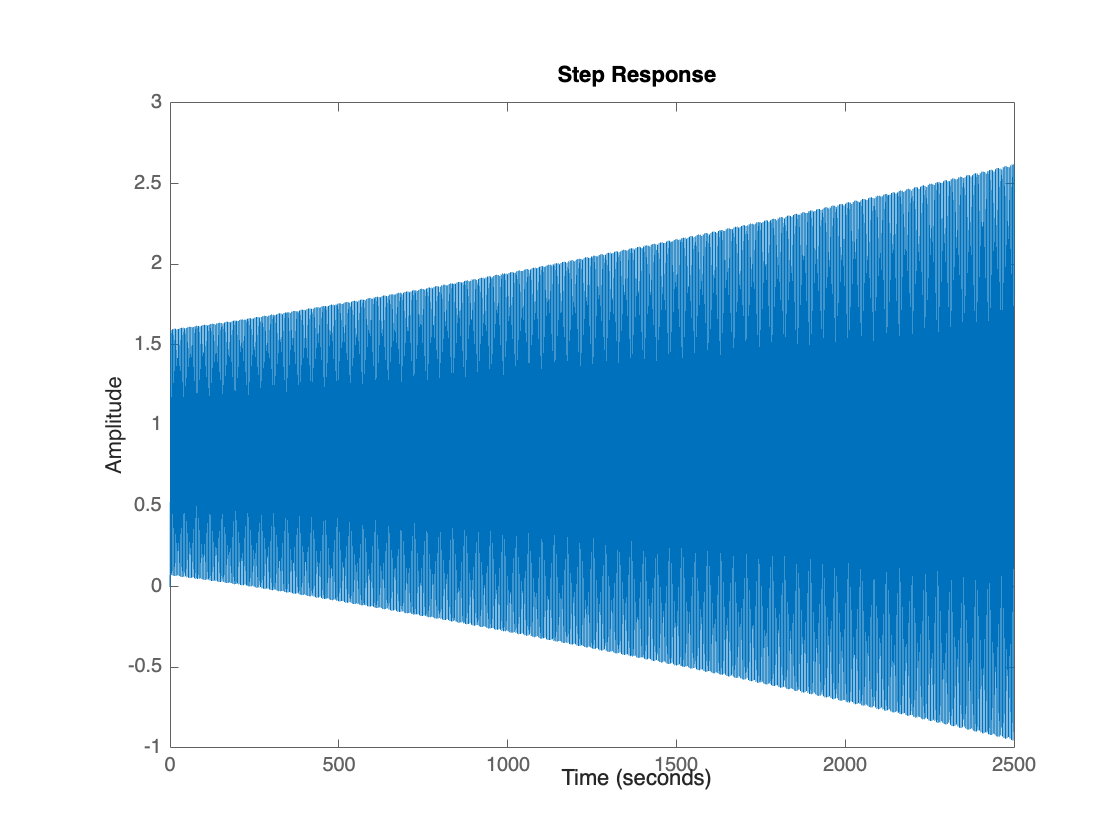


% sistema de malha fechada:
T = L/(1+Gatraso*L);
figure;
step(T)